Significant beta spectrum - same color bar

clear all
close all

diagnosis = {'HC', 'BD', 'SCA',...
    'SCZ', 'ASD', 'MDD' };
plotOrder = [5, 2, 6, 3, 4]; %to match with plot in vbm
nDiag = length(diagnosis); 
hemis = 'left';
load('corr_MBM.mat');
MBM.maps.maskFile = fullfile('/projects/kg98/trangc/VBM/data/MBM', 'fsaverage_164k_cortex-lh_mask.txt'); % path to mask
mask = readmatrix(MBM.maps.maskFile);

MBM.plot.vtkFile = fullfile('/home/trangc/kg98/trangc/VBM/data/MBM', 'fsaverage_164k_midthickness-lh.vtk'); % path to vtk file
% read surface
[vertices,faces] = read_vtk(MBM.plot.vtkFile);
vertices = vertices';
faces = faces';


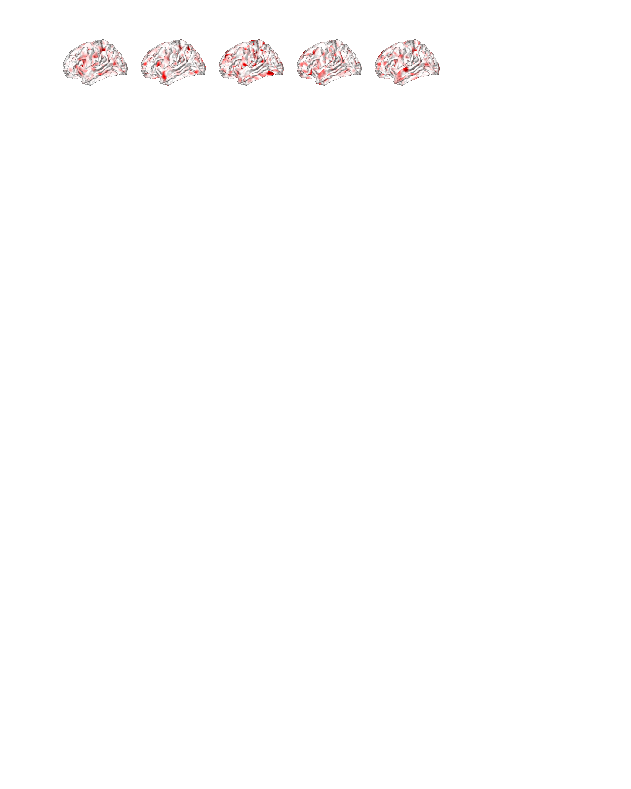


fig = figure('Position', [200 200 2000 2500]);
set(fig,'color','w');
factor_x = 1.2;
factor_y = 1.5;
init_x = 0.1;
init_y = 0.1;
num_row = 10;
num_col = 6;
length_x = (0.82 - init_x)/(factor_x*(num_col-1) + 1);
length_y = (0.95 - init_y)/(factor_y*(num_row-1) + 1);
lineWidth = 2;

font_name = 'Arial';
font_size = 10;
fontsize_legend = 8;

for iDiag = 1:nDiag-1
    
[isDiag locDiag] = ismember(map.diag,num2str(plotOrder(iDiag)));
siteString = (map.site(isDiag));
[siteString] = change_siteName(siteString);
nSite = length(siteString);
maps = (map.gamma(isDiag,:));
for iSite = 1:nSite
    row = ceil(iSite/num_col);
    col = mod(iSite,num_col);
% if iDiag == 5
    ax1 = axes('Position', [init_x+length_x*factor_x*(col-1), init_y+length_y*factor_y*(num_row-row) length_x length_y]);
    % a32 = annotation(fig, 'textbox', [0, ax1.Position(2)+length_y*2, 1, 0.01], 'string', char(diagnosis(plotOrder(iDiag))), 'edgecolor', 'none', ...
    % 'FontName',font_name,'FontSize',font_size, 'horizontalalignment', 'left');
% else
% ax1 = axes('Position', [init_x, init_y+length_y*factor_y*(num_row-iDiag) length_x length_y]);
% a32 = annotation(fig, 'textbox', [0, ax1.Position(2)+length_y, 1, 0.01], 'string', char(diagnosis(plotOrder(iDiag))), 'edgecolor', 'none', ...
%     'FontName',font_name,'FontSize',font_size, 'horizontalalignment', 'left');
% end

dataToPlot(logical(mask)) = maps(iSite,:);

a = patch(ax1, 'Vertices', vertices, 'Faces', faces, 'FaceVertexCData', dataToPlot, ...
    'EdgeColor', 'none', 'FaceColor', 'interp');

if strcmpi(hemis, 'left')
    view(ax1,[-90 0]);
elseif strcmpi(hemis, 'right')
    view(ax1,[90 0]);
end


camlight(ax1,'headlight')
material(a,'dull');
colormap(ax1,bluewhitered(ax1));
axis(ax1,'off');
axis(ax1, 'image');
end
end